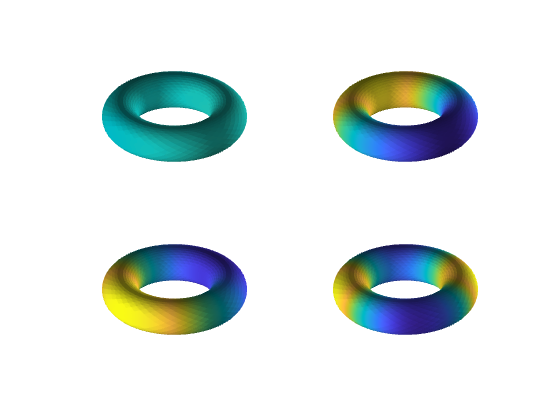

[v,f] = torusMesh(40); 
s = calc_geometric_eigenmode(struct('vertices', v, 'faces', f), 25); 
figure; plotBrain(v,f,[],s.evecs(:,1:4), 'view', {3}); 

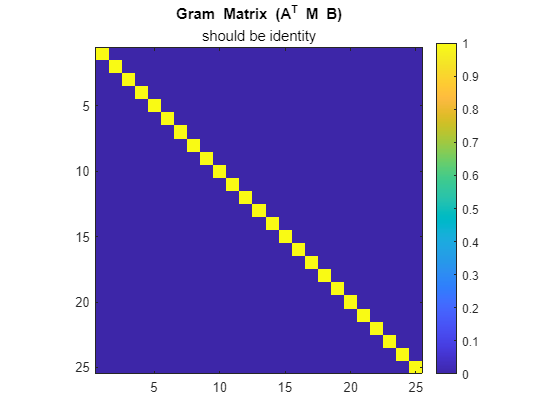

% Pairwise inner products: Identifies mass-orthogonality (should be Identity)
figure; imagescmg(gramw(s.evecs, s.evecs, s.mass)); colorbar; title('Gram Matrix (A^T M B)', 'should be identity')

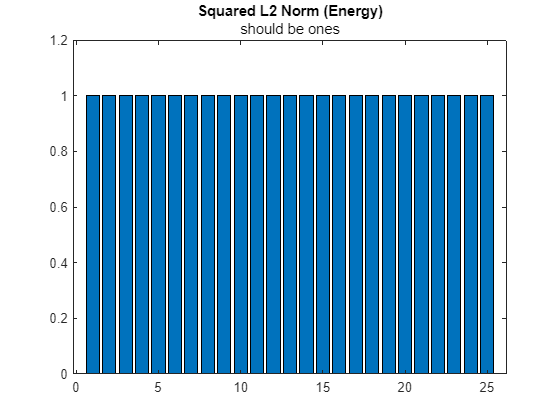


% Column-wise energy: The squared L2-norm of each mode (should be 1s)
figure; bar(ssqw(s.evecs, s.mass)); title('Squared L2 Norm (Energy)', 'should be ones')

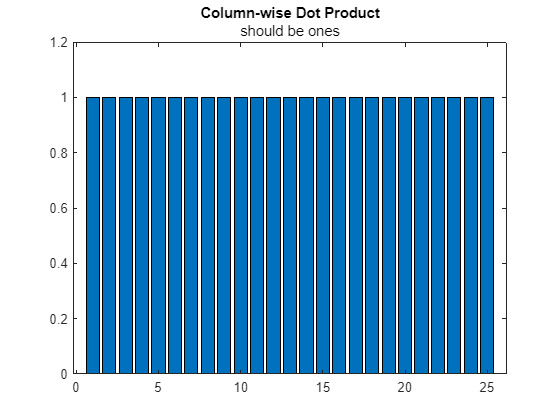


% Comparison dot product: Self-dot product of corresponding columns
figure; bar(dotw(s.evecs, s.evecs, s.mass)); title('Column-wise Dot Product', 'should be ones')

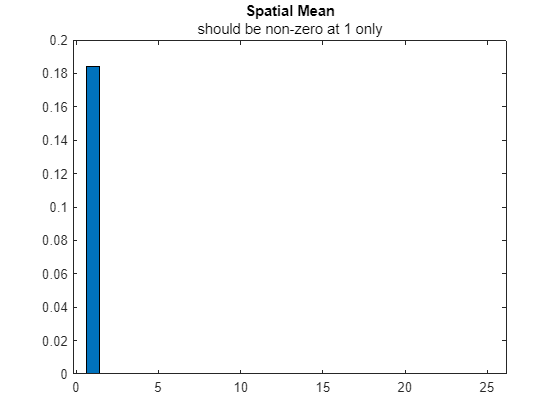

% Spatial Mean: The area-weighted average of each eigenvector
figure; bar(meanw(s.evecs, s.mass)); title('Spatial Mean', 'should be non-zero at 1 only')

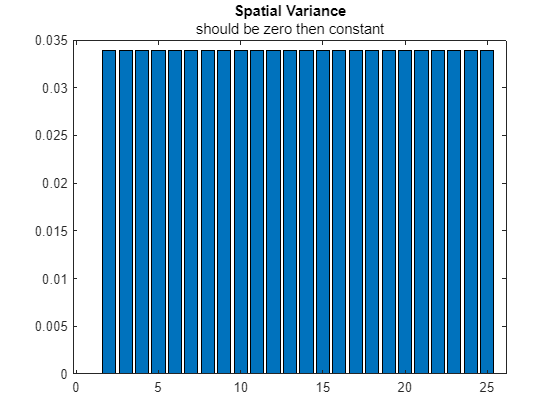


% Spatial Variance: How much the mode's power spreads from its mean
figure; bar(varw(s.evecs, s.mass)); title('Spatial Variance', 'should be zero then constant')

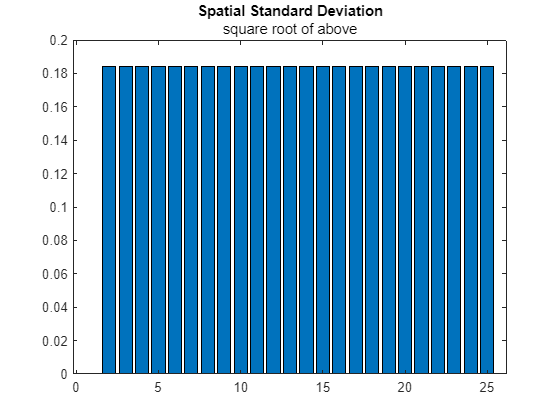


% Spatial Std Dev: The square root of the area-weighted variance
figure; bar(stdw(s.evecs, s.mass)); title('Spatial Standard Deviation', 'square root of above')

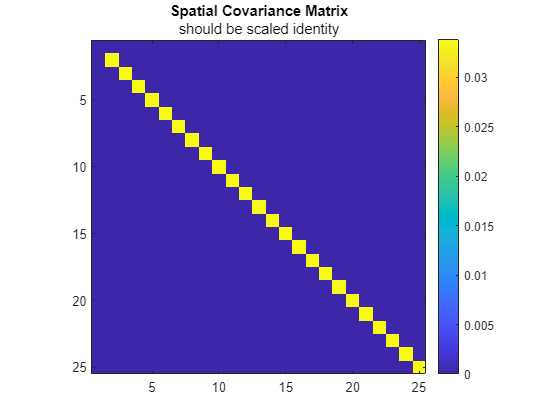


% Covariance Matrix: Full pairwise spatial covariance between modes
figure; imagescmg(covw(s.evecs, s.mass)); colorbar; title('Spatial Covariance Matrix', 'should be scaled identity')

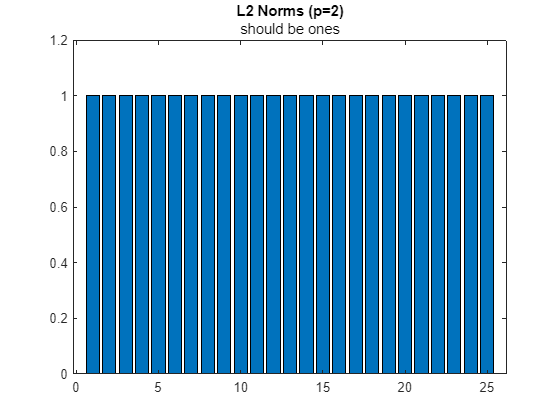

% Area-weighted L2 Norm: Verify if modes are unit-normalized (should all be 1)
figure; bar(vecnormw(s.evecs, s.mass, 2)); title('L2 Norms (p=2)', 'should be ones')

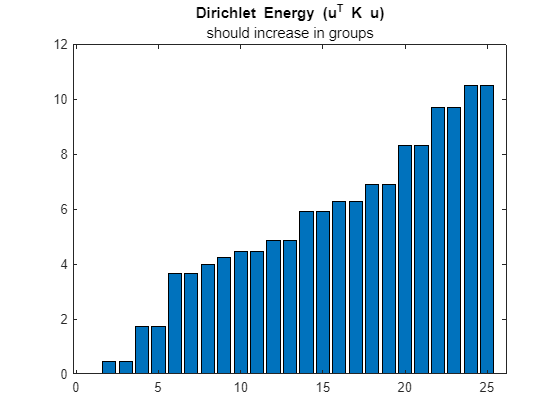

% Dirichlet Energy: Measure of spatial smoothness (gradient energy)
figure; bar(dirichlete(s.evecs, s.stiffness)); title('Dirichlet Energy (u^T K u)', 'should increase in groups')

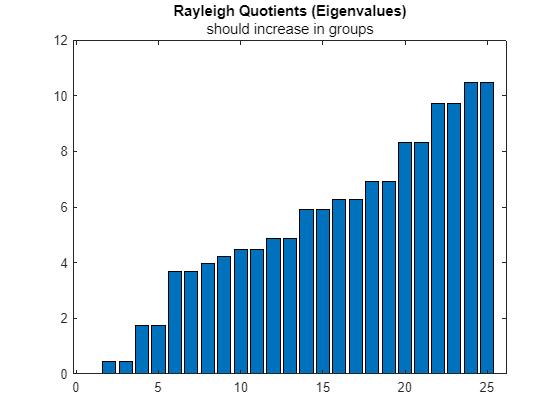


% Rayleigh Quotient: The estimated eigenvalues (Energy / Power)
figure; bar(rayleighq(s.evecs, s.mass, s.stiffness)); title('Rayleigh Quotients (Eigenvalues)', 'should increase in groups')

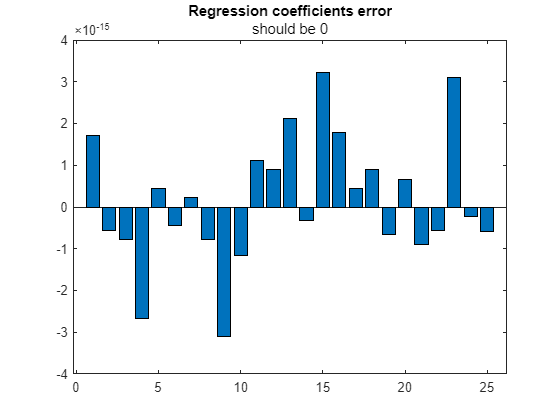

% Create a dummy map y (Mode 3 + noise) and solve for coefficients beta
% Generate data with known coefficients
b_true = randn(width(s.evecs), 1);
b_est = mldividew(s.evecs, s.evecs * b_true, s.mass);
figure; bar(b_est-b_true); title('Regression coefficients error', 'should be 0'); 

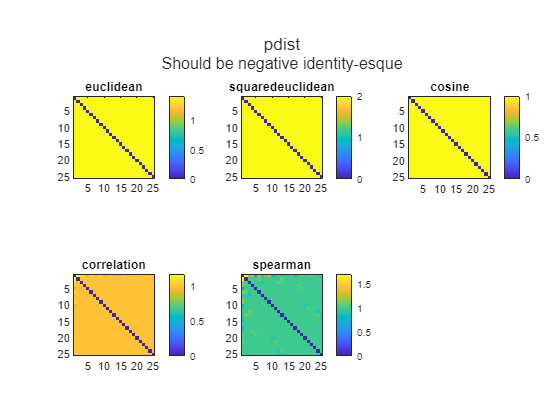

figure; 
Distances = {'euclidean', 'squaredeuclidean', 'cosine', 'correlation', 'spearman'};
tl = multiplot(Distances, @(x) imagescmg(squareform(pdistw(s.evecs, s.mass, x))), ...
    @(n) title(Distances{n}));
title(tl, 'pdist', 'Should be negative identity-esque'); 

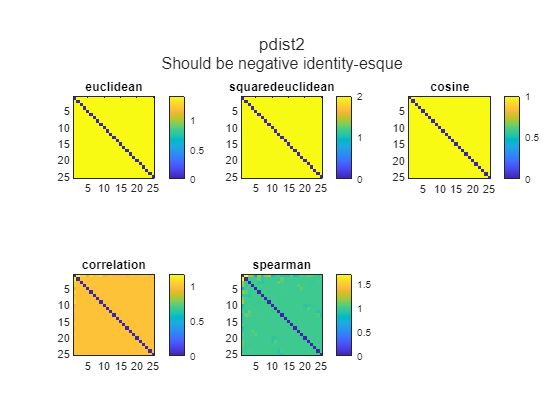

figure; 
Distances = {'euclidean', 'squaredeuclidean', 'cosine', 'correlation', 'spearman'};
tl = multiplot(Distances, @(x) imagescmg(pdist2w(s.evecs, s.evecs, s.mass, x)), ...
    @(n) title(Distances{n}));
title(tl, 'pdist2', 'Should be negative identity-esque'); 

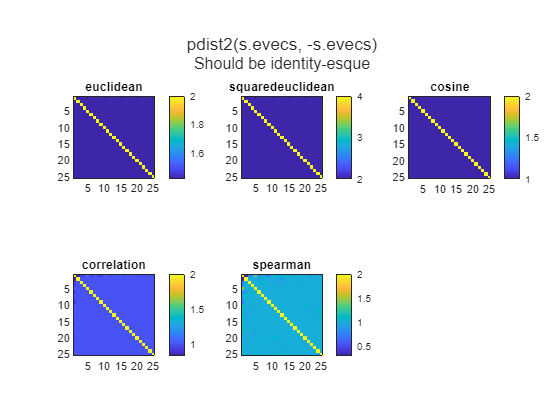

figure; 
Distances = {'euclidean', 'squaredeuclidean', 'cosine', 'correlation', 'spearman'};
tl = multiplot(Distances, @(x) imagescmg(pdist2w(s.evecs, -s.evecs, s.mass, x)), ...
    @(n) title(Distances{n}));
title(tl, 'pdist2(s.evecs, -s.evecs)', 'Should be identity-esque'); 